# MATLAB で Audio Plugin 開発

**# 02 イコライザ**

松本 和樹 (早稲田大学，MATLAB Student Ambassador)

## フィルタ係数の計算

設定

fs   =  16000;                       % サンプリング周波数
fc   = 267.2; % カットオフ周波数
Q    = 6.3224; % レゾナンス
type = "BPF";         % フィルタの種類

係数の計算

switch type
    case "LPF"
        wc    = 2*pi*fc/fs;
        alpha = sin(wc)/(2*Q);
        cosw0 = cos(wc);
        
        % b = [b0 b1 b2], a = [a0 a1 a2]
        b = [ (1-cosw0)/2,1-cosw0,(1-cosw0)/2]; 
        a = [1+alpha,-2*cosw0,1-alpha];
    case "HPF"
        [b,a] = calcHPFCoeffs(fc,fs,Q); % 略

    case "BPF"
        [b,a] = calcBPFCoeffs(fc,fs,Q); % 略
end

特性の可視化

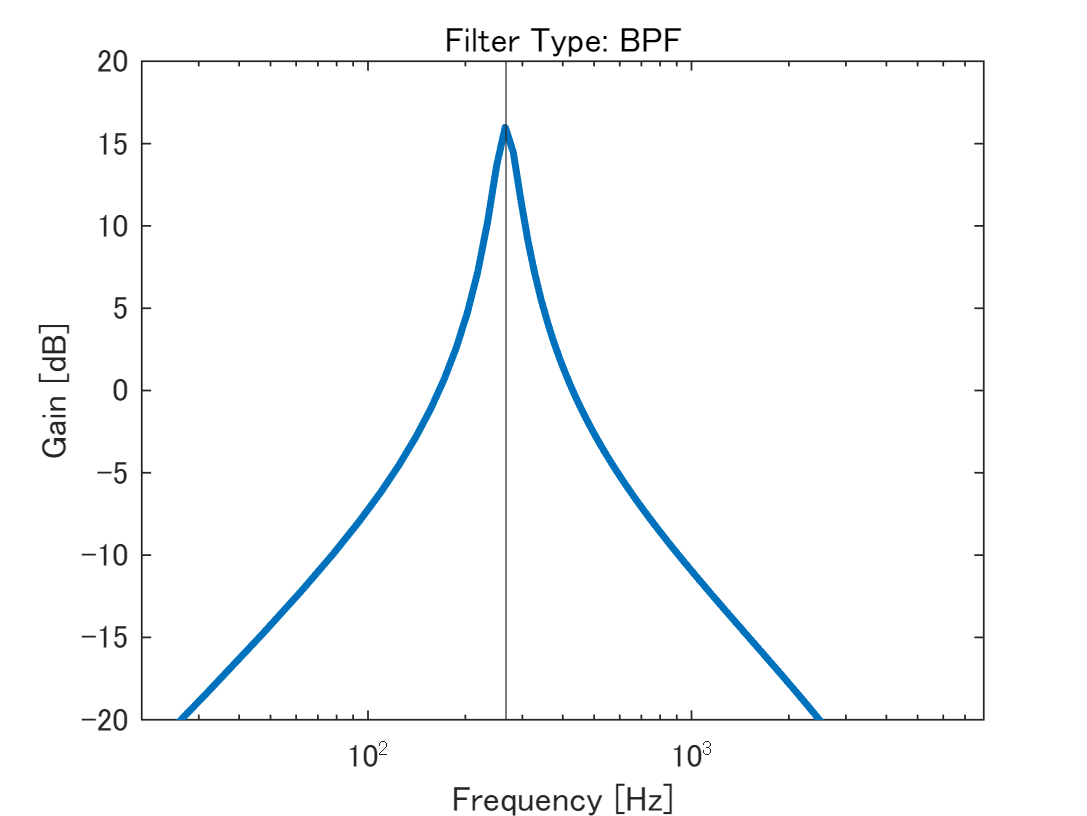

[h,f]=freqz(b,a,[],fs);             % 周波数特性を計算．
plot(f,mag2db(abs(h)),LineWidth=2); % 振幅特性（＝ h の絶対値を dB に変換したもの）をプロット

% 見栄えを整える
xscale("log")   ; xlabel("Frequency [Hz]"); xlim([20,8000]); xline(fc);
yscale("linear"); ylabel("Gain [dB]")     ; ylim([-20,20]) ;
title("Filter Type: "+type);

フィルタの適用

x = randn(fs*0.5,1); % 0.5 秒の雑音を生成
y = filter(b,a,x);   % フィルタを適用
soundsc(y,fs);

## フレームベース処理

正弦波の作成（1 フレーム = 1024 サンプル）

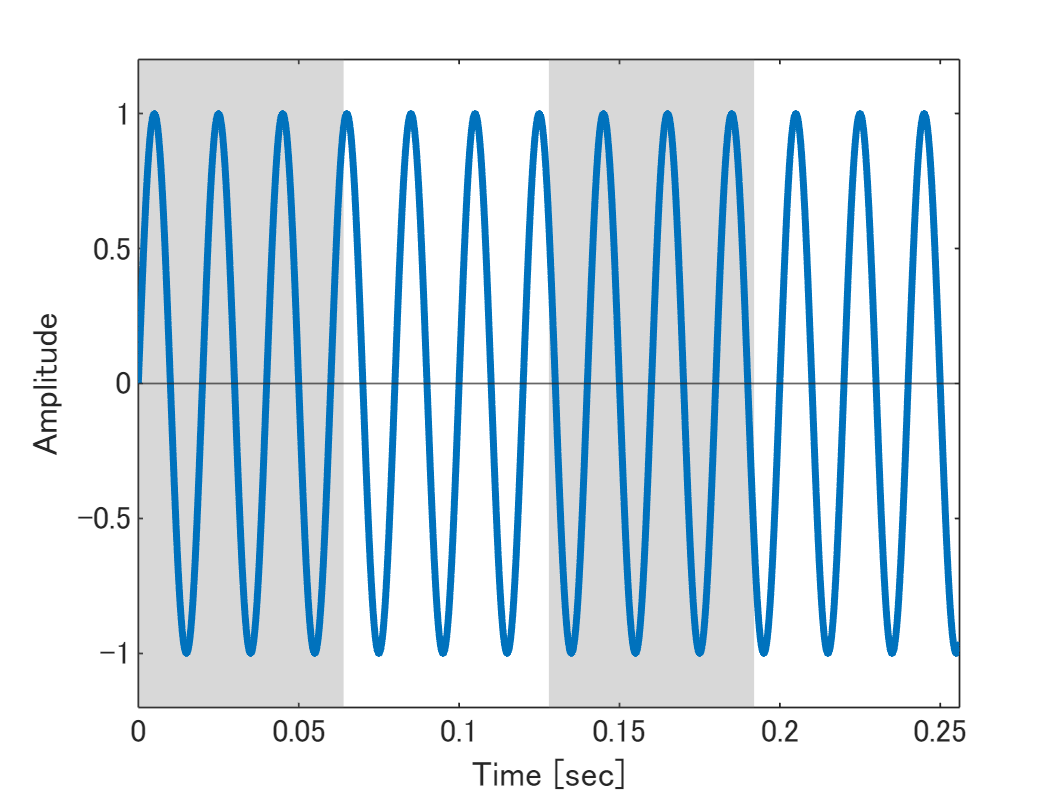

fs = 16000;
t  = (0:4095)'/fs;
x  = sin(2 * pi * 50 * t);
x1 = x(1:1024,:);
x2 = x(1025:2048,:);
x3 = x(2049:3072,:);
x4 = x(3073:4096,:);

figure;
showFirstFourFrames(t,x,fs,1024);

ハイパスフィルタ

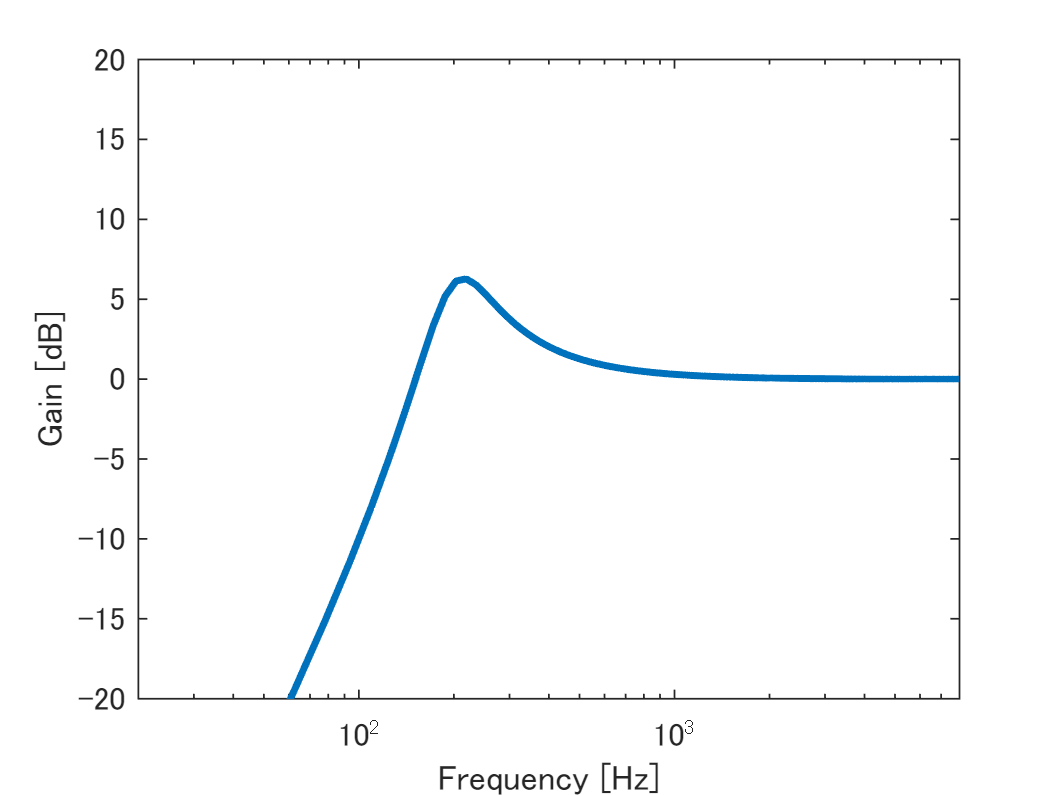

[b,a] = exampleHPF;

よくない実装の例

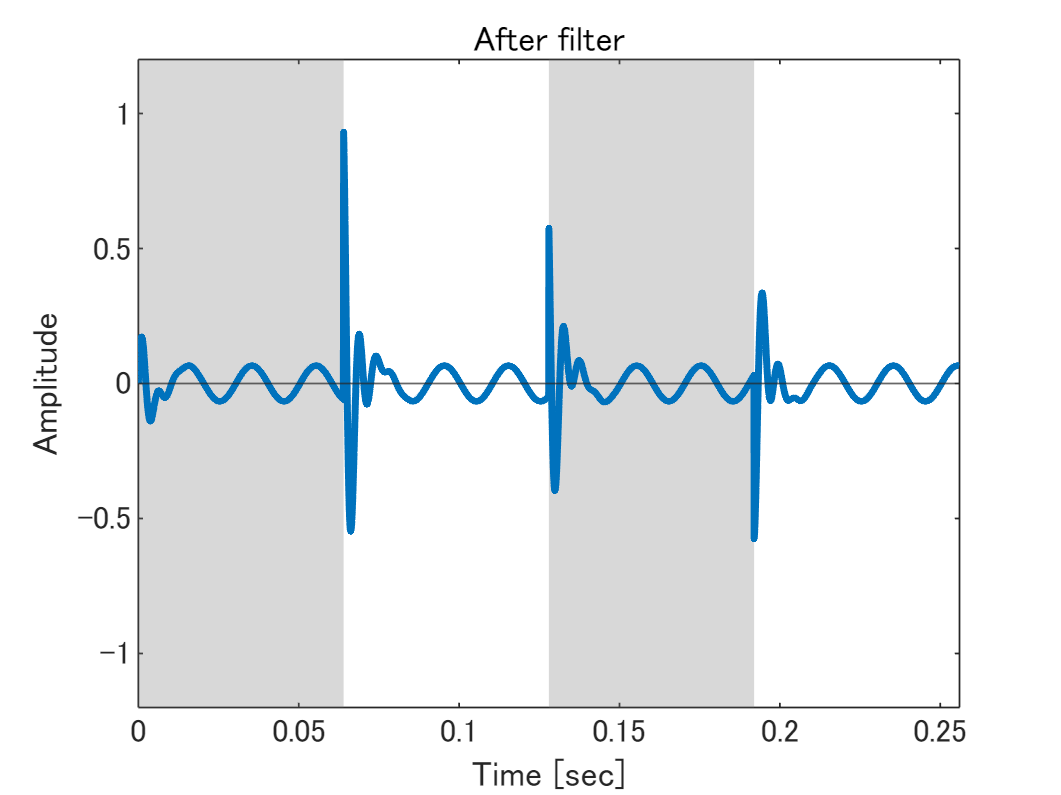

y1    = filter(b,a,x1);   % 1 フレーム目
y2    = filter(b,a,x2);   % 2 フレーム目
y3    = filter(b,a,x3);   % 3 フレーム目
y4    = filter(b,a,x4);   % 4 フレーム目
y     = [y1;y2;y3;y4];    % 出力

showFirstFourFrames(t,y,fs,1024);
title("After filter")

sound(y,fs);

適切な実装の例

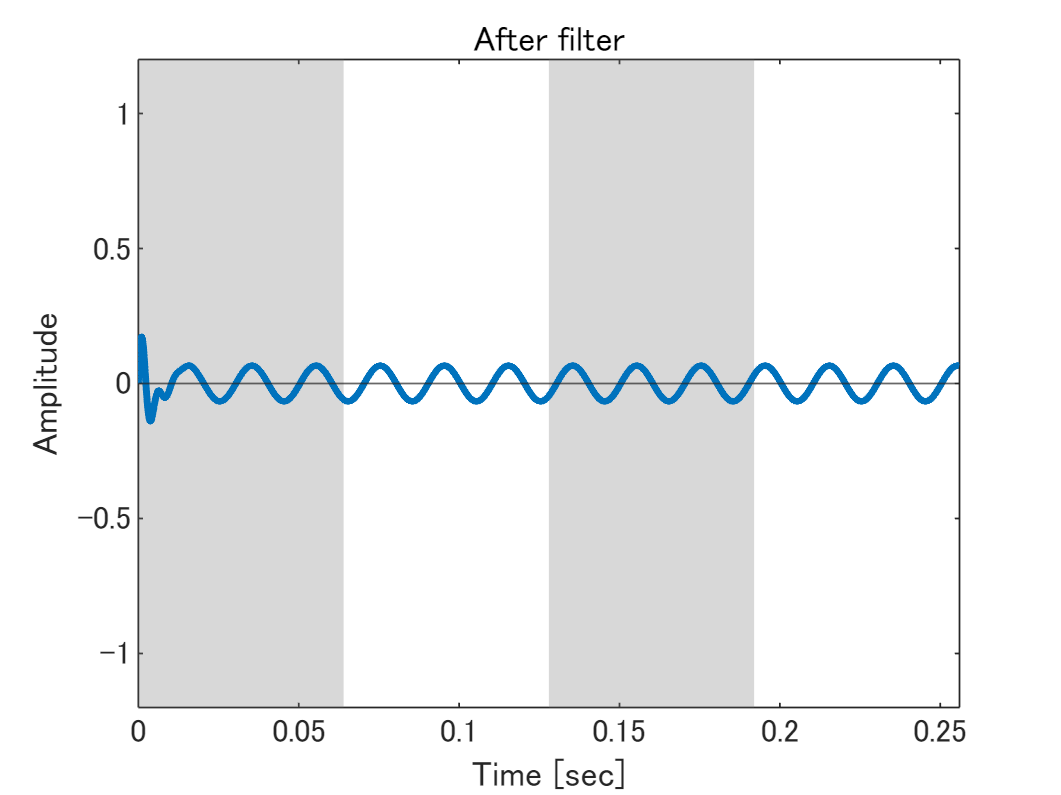

  z    = zeros(2,1);       % 遅延器の状態の初期化
[y1,z] = filter(b,a,x1,z); % 1 フレーム目
[y2,z] = filter(b,a,x2,z); % 2 フレーム目
[y3,z] = filter(b,a,x3,z); % 3 フレーム目
[y4,z] = filter(b,a,x4,z); % 4 フレーム目
y      = [y1;y2;y3;y4];    % 出力

showFirstFourFrames(t,y,fs,1024);
title("After filter")

sound(y,fs);

## プラグインのテスト・検証・生成

audioTestBench("MATLAB_EQ")

validateAudioPlugin("MATLAB_EQ")

generateAudioPlugin("MATLAB_EQ")

## スライド用

fs   = 16000;
fc   = 800;
Q    = 2;

setDefaultInterpreterLaTeX;

figure;
hold on;

[b,a] = calcLPFCoeffs(fc,fs,Q);
[h,f]=freqz(b,a,4096,fs);           
plot(f,mag2db(abs(h)),LineWidth=2,DisplayName="Low pass"); 

[b,a] = calcHPFCoeffs(fc,fs,Q);
[h,f]=freqz(b,a,4096,fs);           
plot(f,mag2db(abs(h)),LineWidth=2,DisplayName="High pass"); 

[b,a] = calcBPFCoeffs(fc,fs,Q);
[h,f]=freqz(b,a,4096,fs);           
plot(f,mag2db(abs(h)),LineWidth=2,DisplayName="Band pass");

legend(AutoUpdate="off",Location="northwest");
xscale("log")   ; xlabel("Frequency [Hz]"); xlim([20,8000]); 
yscale("linear"); ylabel("Gain [dB]")     ; ylim([-20,20]) ;
xline(fc,"k-","$f_c$",LabelOrientation="horizontal");
box on;
grid on;
fontsize(15,"points"); print("docs/assets/images/02/filters.svg",'-dsvg');

addoperatorH = @(left,right,text,fontsize) annotation("textbox",...
                                [left.Position(1)+left.Position(3) ...
                                 left.Position(2) ...
                                 right.Position(1) - (left.Position(3) + left.Position(1)) ...
                                 left.Position(4)], ...
                                 "String",text, ...
                                 "FontSize", fontsize, ...
                                 HorizontalAlignment="center", ...
                                 VerticalAlignment="middle", ...
                                 EdgeColor="none", ...
                                 Interpreter="latex", ...
                                 FitBoxToText="on");

fs = 16000;
t  = (0:4095)'/fs;
x  = sin(2 * pi * 50 * t);
x1 = x(1:1024,:);
x2 = x(1025:2048,:);
x3 = x(2049:3072,:);
x4 = x(3073:4096,:);

figure;
tiledlayout(2,4);
nexttile(2,[1 2]); 
[b,a] = exampleHPF; 
xticks([1e2 1e3])
xticklabels(["100", "1k"])
title("Frequency response of HPF")
xline(50,"--","50 Hz");

before=nexttile(5,[1 2]); 
showFirstFourFrames(t,x,fs,1024); 
xticks([]); yticks([]);
title("Before")
xlabel("Time");

y1 = filter(b,a,x1); % 1 フレーム目
y2 = filter(b,a,x2); % 2 フレーム目
y3 = filter(b,a,x3); % 3 フレーム目
y4 = filter(b,a,x4); % 4 フレーム目
y  = [y1;y2;y3;y4];  % 出力

after=nexttile(7,[1 2]); showFirstFourFrames(t,y,fs,1024); xticks([]); yticks([]);
title("After")
delete(gca().Children(4))
ylabel("");
xlabel("Time");
fontsize(12,"points")

annotation("textbox",gca().Position+[0 -0.02 0 0], ...
    "String","$?$", ...
    "FontSize", 50, ...
    HorizontalAlignment="center", ...
    VerticalAlignment="middle", ...
    EdgeColor="none", ...
    Interpreter="latex");

addoperatorH(before,after,"$\to$",20);
addoperatorH(before,after,"HPF"+newline+newline,10);

print("docs/assets/images/02/implementation_example.svg",'-dsvg');

figure;

tiledlayout(2,4);

nexttile(2,[1 2]); 
[b,a] = exampleHPF; 
xticks([1e2 1e3])
xticklabels(["100", "1k"])
title("Frequency response of HPF")
xline(50,"--","50 Hz");

before=nexttile(5,[1 2]); 
showFirstFourFrames(t,x,fs,1024); 
xticks([]); yticks([]);
title("Before")
xlabel("Time");

y1 = filter(b,a,x1); % 1 フレーム目
y2 = filter(b,a,x2); % 2 フレーム目
y3 = filter(b,a,x3); % 3 フレーム目
y4 = filter(b,a,x4); % 4 フレーム目
y  = [y1;y2;y3;y4];  % 出力

after=nexttile(7,[1 2]); showFirstFourFrames(t,y,fs,1024); xticks([]); yticks([]);
title("After: y=filter(b,a,x)")
ylabel("");
xlabel("Time");

fontsize(12,"points")
addoperatorH(before,after,"$\to$",20);
addoperatorH(before,after,"HPF"+newline+newline,10);

print("docs/assets/images/02/implementation_bad.svg",'-dsvg');

figure;
tiledlayout(2,4);

nexttile(2,[1 2]); 
[b,a] = exampleHPF; 
xticks([1e2 1e3])
xticklabels(["100", "1k"])
title("Frequency response of HPF")
xline(50,"--","50 Hz");

before=nexttile(5,[1 2]); 
showFirstFourFrames(t,x,fs,1024); 
xticks([]); yticks([]);
title("Before")
xlabel("Time");

z      = zeros(2,1);       % 内部状態の初期化
[y1,z] = filter(b,a,x1,z); % 1 フレーム目
[y2,z] = filter(b,a,x2,z); % 2 フレーム目
[y3,z] = filter(b,a,x3,z); % 3 フレーム目
[y4,z] = filter(b,a,x4,z); % 4 フレーム目
y      = [y1;y2;y3;y4];    % 出力

after=nexttile(7,[1 2]); showFirstFourFrames(t,y,fs,1024); xticks([]); yticks([]);
title("After: [y,z]=filter(b,a,x,z)")
ylabel("");
xlabel("Time");

fontsize(12,"points")
addoperatorH(before,after,"$\to$",20);
addoperatorH(before,after,"HPF"+newline+newline,10);

print("docs/assets/images/02/implementation_good.svg",'-dsvg');

function showFirstFourFrames(t,y,fs,frameLength)
plot(t,y,LineWidth=2);
xregion(0, frameLength/fs);
xregion(2*frameLength/fs, 3*frameLength/fs);
xlim([0 4*frameLength/fs]);
ylim([-1.2 1.2]);
yline(0)
xlabel("Time [sec]");
ylabel("Amplitude");
end

function setDefaultInterpreterLaTeX
defaults            = fieldnames(get(groot,"factory"));
interpreterSettings = defaults(contains(defaults,"Interpreter"));
for i = 1:numel(interpreterSettings)
    set(groot, replace(interpreterSettings{i},"factory","default"),"latex")
end
end

function [b,a] = exampleHPF
fs    = 16000;
fc    = 200;
Q     = 2;
[b,a] = calcHPFCoeffs(fc,fs,Q);
[h,f] = freqz(b,a,[],fs);           % 周波数特性を計算

plot(f,mag2db(abs(h)),LineWidth=2); % 振幅特性を可視化
xscale("log")   ; xlabel("Frequency [Hz]"); xlim([20,8000]);
yscale("linear"); ylabel("Gain [dB]")     ; ylim([-20,20]) ;
end